# Build input signal trace

Generate data.

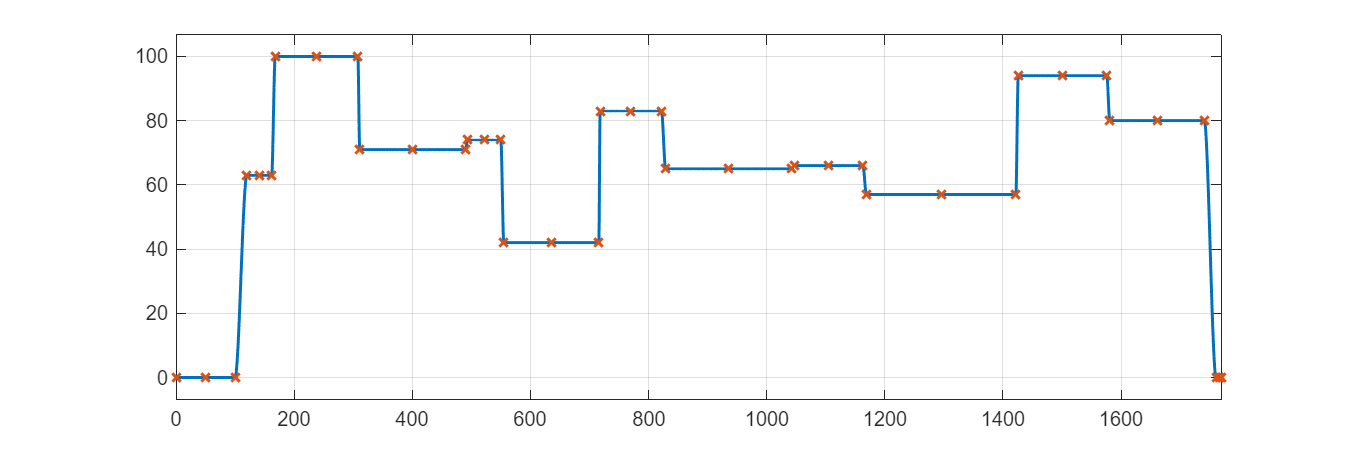

signal_design_matrix = SignalTool3.generateSignalDesignMatrixFromTraceProperties(...
  RandomSeed = 25, ...
  FInitialValue = 0, ...
  XInitialFlatLength = 100, ...
  XInitialTransitionLength = 20, ...
  NumTransitions = 10, ...
  TransitionXRange = [1 10], ...
  FlatXRange = [10 300], ...
  FRange = [40 100], ...
  XFinalTransitionLength = 20, ...
  XFinalFlatLength = 10, ...
  FFinalValue = 0 );

data_table = SignalTool3.getVectorsFromSignalDesignMatrix(signal_design_matrix);

t = data_table.X;
f = data_table.F;

fig = figure;
fig.Position(3:4) = [900 300];  % width height
SignalTool3.plotLookupTable1D(t, f, InterpolationInterval=0.5, ParentAxes=axes(fig))

Set the generated data to the target block in the target model.

% set_param modifies the model file. Uncomment to use the code.
%{
model_name = "Inputs_BEVController_Random_refsub";
load_system(model_name)

block_path = model_name + "/Vehicle speed reference";

% Target block is Simulink 1D Lookup Table.
set_param(block_path, "Table", CodeTool1.stringify(f))
set_param(block_path, "BreakpointsForDimension1", CodeTool1.stringify(t))
%}

*Copyright 2025-2026 The MathWorks, Inc.*